# Parametry działania

Powtarzalne wyniki

close all ;
rng('default') ;

% Liczba obrazów treningowych na klasę
cnt_train = 70 ;

% Liczba obrazów testowych na klasę
cnt_test = 30;

% Wybrane klasy obiektów
img_classes = {'deli', 'greenhouse', 'bathroom'};

% Liczba cech wybierana na każdym obrazie
feats_det = 100;

% Metoda wyboru cech (true - jednorodnie w całym obrazie, false - najsilniejsze)
feats_uniform = true;

% Wielkość słownika
words_cnt = 30 ;

% Detekcja cech
% Ładowanie pełnego zbioru danych z automatycznym podziałem na klasy
% Zbiór danych pochodzi z publikacji: A. Quattoni, and A.Torralba. <http://people.csail.mit.edu/torralba/publications/indoor.pdf
% _Recognizing Indoor Scenes_>. IEEE Conference on Computer Vision and Pattern
% Recognition (CVPR), 2009.
%
% Pełny zbiór dostępny jest na stronie autorów: <http://web.mit.edu/torralba/www/indoor.html
% http://web.mit.edu/torralba/www/indoor.html>

imds_full = imageDatastore("indoor", "IncludeSubfolders", true, "LabelSource", "foldernames");
%countEachLabel(imds_full)

% Wybór przykładowych klas i podział na zbiór treningowy i testowy
[imds, imtest] = splitEachLabel(imds_full, cnt_train, cnt_test, 'Include', img_classes);
%countEachLabel(imds)

% Wyznaczenie punktów charakterystycznych we wszystkich obrazach zbioru treningowego
files_cnt = length(imds.Files);
all_points = cell(files_cnt, 1);
total_features = 0;

for i=1:files_cnt
    I = readImage(imds.Files{i});
    all_points{i} = getFeaturePoints(I, feats_det, feats_uniform);
    total_features = total_features + length(all_points{i});
end

% Przygotowanie listy przechowującej indeksy plików i punktów charakterystycznych
file_ids = zeros(total_features, 2);
curr_idx = 1;
for i=1:files_cnt
    file_ids(curr_idx:curr_idx+length(all_points{i})-1, 1) = i;
    file_ids(curr_idx:curr_idx+length(all_points{i})-1, 2) = 1:length(all_points{i});
    curr_idx = curr_idx + length(all_points{i});
end

% Obliczenie deskryptorów punktów charakterystycznych
all_features = zeros(total_features, 64, 'single');
curr_idx = 1;
for i=1:files_cnt
    I = readImage(imds.Files{i});
    curr_features = extractFeatures(rgb2gray(I), all_points{i});
    all_features(curr_idx:curr_idx+length(all_points{i})-1, :) = curr_features;
    curr_idx = curr_idx + length(all_points{i});
end

% Tworzenie słownika

% Klasteryzacja punktów
[idx, words, sumd, D] = kmeans(all_features, words_cnt, "MaxIter", 10000);
% Wizualizacja wyliczonych słów

% Wyznaczenie histogramów słów dla każdego obrazu treningowego
file_hist = zeros(files_cnt, words_cnt);
for i=1:files_cnt
    file_hist(i,:) = histcounts(idx(file_ids(:,1) == i), (1:words_cnt+1)-0.5, 'Normalization', 'probability');
end

% Wyznaczenie histogramów słów dla każdego obrazu testowego
test_hist = zeros(length(imtest.Files), words_cnt);
for i=1:length(imtest.Files)
    I = readImage(imtest.Files{i});
    pts = getFeaturePoints(I, feats_det, feats_uniform);
    feats = extractFeatures(rgb2gray(I), pts);
    test_hist(i,:) = wordHist(feats, words);
end

## SVM - przykład

Uczenie wieloklasowego klasyfikatora SVM o parametrach C i gamma. Rozpoznawanie wielu klas opiera się na regule one-vs-one

C = 0.1 ;
gamma = 0.1 ;
temp = templateSVM('KernelFunction', 'gaussian', 'BoxConstraint', C, 'KernelScale', gamma) ;
model = fitcecoc(file_hist, imds.Labels, 'Learners', temp) ;
train_err = loss(model, file_hist, imds.Labels, 'Lossfun', 'classiferror') ;
test_err = loss(model, test_hist, imtest.Labels, 'Lossfun', 'classiferror') ;
fprintf(1,'train_acc: %f, test_acc: %f\n', 1-train_err, 1-test_err) ;

train_acc: 0.971429, test_acc: 0.866667



cv_errs = []


cv_errs =

     []



ks = [2:20]

ks =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


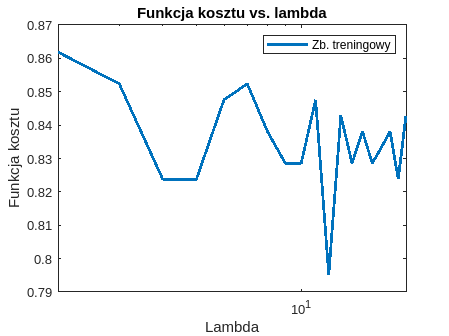

for k = ks
    % Kroswalidacja klasyfikatora w podziale na zbioru 4:1
    modelcv = crossval(model, 'KFold', k) ; % Model 'kroswalidowany'
    modelcv.Trained; % Model 'kroswalidowany' zawiera w sobie faktycznie 5 modeli - każdy uczony przy innym podziale zbioru
    cv_errs = [cv_errs, 1-kfoldLoss(modelcv)] ; % Zagregowany błąd kroswalidacji
    %fprintf(1,'cross_validation_accuracy: %f\n', 1-cv_err) ;
end

figure
semilogx(ks, cv_errs, 'LineWidth', 2) ;
title('Funkcja kosztu vs. lambda') ;
xlabel('Lambda') ;
ylabel('Funkcja kosztu') ;
legend('Zb. treningowy','Zb. walidacyjny') ;

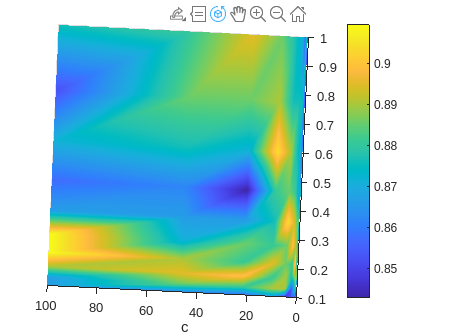

k = 7;
g_range = logspace(-1, 0, 10);
c_range = logspace(-1, 2, 10);

[G, C] = meshgrid(g_range, c_range);
% Ensure output matrix matches X and Y size
results = zeros(size(G));  

% Loop through each grid point and evaluate the scalar function
for i = 1:size(G, 1)
    for j = 1:size(G, 2)
        results(i,j) = calc(C(i,j), G(i,j), file_hist, imds, k);
    end
end

figure;
surf(G, C, results);
xlabel('gamma'); ylabel('c'); zlabel('Skutecznosc');
shading interp;
% view(0,90)
colorbar;

C = 100 ;
gamma = 0.215 ;
temp = templateSVM('KernelFunction', 'gaussian', 'BoxConstraint', C, 'KernelScale', gamma) ;
model = fitcecoc(file_hist, imds.Labels, 'Learners', temp) ;
train_err = loss(model, file_hist, imds.Labels, 'Lossfun', 'classiferror') ;
test_err = loss(model, test_hist, imtest.Labels, 'Lossfun', 'classiferror') ;
fprintf(1,'train_acc: %f, test_acc: %f\n', 1-train_err, 1-test_err) ;

train_acc: 1.000000, test_acc: 0.900000


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.095238 |     0.16138 |    0.095238 |    0.095238 |       4.9985 |      0.31698 |
|    2 | Accept |     0.15714 |     0.11589 |    0.095238 |    0.099408 |      0.16828 |       331.45 |
|    3 | Accept |     0.66667 |     0.11427 |    0.095238 |    0.095269 |    0.0024998 |    0.0012013 |
|    4 | Accept |     0.13333 |      0.1199 |    0.095238 |    0.095263 |       995.29 |       26.743 |
|    5 | Accept |     0.15714 |     0.11637 |    0.095238 |     0.09528 |       13.309 |       315.13 |
|    6 | Accept |     0.12857 |     0.11864 |    0.095238 |    0

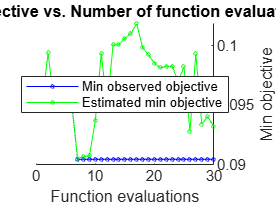

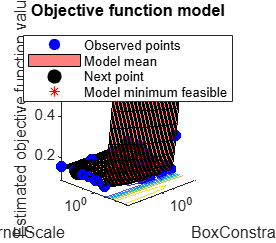

% Define the hyperparameter optimization
opt = struct('AcquisitionFunctionName', 'expected-improvement-plus');

% Train SVM with Bayesian Optimization
SVMModel = fitcecoc(file_hist, imds.Labels, ...
    'Learners', temp, ...
    'OptimizeHyperparameters', {'BoxConstraint', 'KernelScale'}, ...
    'HyperparameterOptimizationOptions', opt);


% Extract the best hyperparameters
best_C = SVMModel.HyperparameterOptimizationResults.XAtMinObjective.BoxConstraint

best_C = 144.7625

best_gamma = SVMModel.HyperparameterOptimizationResults.XAtMinObjective.KernelScale

best_gamma = 0.1362

best_cv_error = SVMModel.HyperparameterOptimizationResults.MinObjective;
best_cv_accuracy = 1 - best_cv_error

best_cv_accuracy = 0.9095

C = 144.7625 ;
gamma = 0.1362 ;
temp = templateSVM('KernelFunction', 'gaussian', 'BoxConstraint', C, 'KernelScale', gamma) ;
model = fitcecoc(file_hist, imds.Labels, 'Learners', temp) ;
train_err = loss(model, file_hist, imds.Labels, 'Lossfun', 'classiferror') ;
test_err = loss(model, test_hist, imtest.Labels, 'Lossfun', 'classiferror') ;
fprintf(1,'train_acc: %f, test_acc: %f\n', 1-train_err, 1-test_err) ;

train_acc: 1.000000, test_acc: 0.911111


## Funkcje pomocnicze

function result = calc(C, gamma, file_hist, imds, k)
    temp = templateSVM('KernelFunction', 'gaussian', 'BoxConstraint', C, 'KernelScale', gamma) ;
    model = fitcecoc(file_hist, imds.Labels, 'Learners', temp) ;
    modelcv = crossval(model, 'KFold', k) ; % Model 'kroswalidowany'
    result = 1-kfoldLoss(modelcv);
end

function pts = getFeaturePoints(I, pts_det, pts_uniform)
if size(I, 3) > 1
    I2 = rgb2gray(I);
else
    I2 = I;
end

pts = detectSURFFeatures(I2, 'MetricThreshold', 100);
if pts_uniform
    pts = selectUniform(pts, pts_det, size(I));
else
    pts = pts.selectStrongest(pts_det);
end
end

function h = wordHist(feats, words)
words_cnt = size(words, 1);
dis = pdist2(feats, words, 'squaredeuclidean');
[~, lbl] = min(dis, [], 2);
h = histcounts(lbl, (1:words_cnt+1)-0.5, 'Normalization', 'probability');
end

% Wczytanie obrazu i przeskalowanie jeśli jest zbyt duży
function I = readImage(path)
I = imread(path);
if size(I,2) > 640
    I = imresize(I, [NaN 640]);
end
end